# Influence of the gryroscopic effect in rotor dynamic

#### System parameter

clear all
L = 1;         % length in mm    
Ri = 0;          % inner radius in mm
Ra = 8e-3;            % outer radius in mm
rho = 7.85e3;    % density in kg/mm^3
E = 2.0e11;       % Youngs modulus in MPa

#### Finite-element discretization

The elastic rotor shaft is discretized by two-noded beam elements. The beam axis coincides with the global x-axes and is at the same time also the rotation axes. Kinematical assumptions are according to Bernoulli.

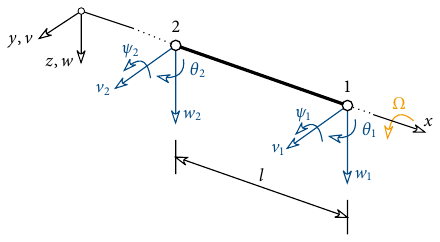

All nodal values are written in the vector ***u*** in the following sequence

.

24 elements are used to discretize the complete shaft.

numEL = 24;

Subsequently, the structure array `FE` is build up. By several fields the complete finite-element discreitization is defined.

**Nodes**

Coordinates of the nodes along the x-axes

FE.N  = linspace(0,L,numEL+1);

**Elements**

Each row of the field `E` defines one element. The first column is the right node, the second colum the left node.

FE.E  = [ (2:numEL+1)' (1:(numEL))' ];

**Cross section**

The cross section properties are defined in the field `SC`. The columns correspond to the Youngs modulus, density, inner radius and outer radius. Each row defines the properties for one element, whereby the row index corresponds to the element number, as defined in the field `E`. 

FE.SC = [ E*ones(numEL,1)  rho*ones(numEL,1)  Ri*ones(numEL,1)  Ra*ones(numEL,1) ];

**Boundary conditions**

The first row of the field `BC` corresponds to the node number of the constrained. In the second column the local degree of freedom, which is set to zero, is defined.

FE.BC = [ 4  1      % displacement in z-direction
          4  3      % displacement in y-direction
         22  1
         22  3 ];

**Rigid disks**

Rigid disks are defined in the field RD. The first columns correspond to the node number, where the rigid disk is mounted to the rotor, mass, polar mass moment of inertia and the diametral mass moment of intertia.

FE.RD = [   6,  2.466150, 0.006165375, 0.012330751
           14,  2.466150, 0.006165375, 0.012330751 ];

Plot discretization

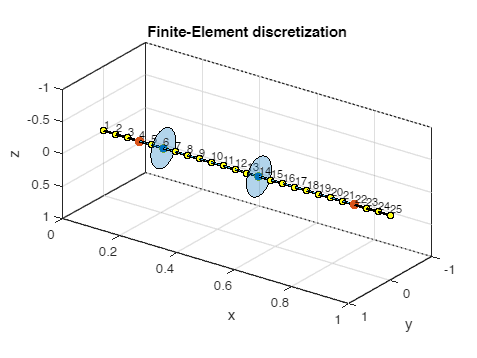

preProc(FE);
title('Finite-Element discretization')

#### Finite-element procedure

Here, the global mass, gyroscopic and stiffness matrix are assembled of the rotor system according to the direct stiffness method. 

% number of degrees of freedom
numDOF = length(FE.N)*4;

% initialze system matrices
K = zeros(numDOF,numDOF);
M = zeros(numDOF,numDOF);
G = zeros(numDOF,numDOF);

% --- BEAM ELEMENTS ---
% loop over all beam elements
for i=1:numEL

    % coordinates and length of the element
    x = FE.N(FE.E(i,:));
    l = abs(x(1) - x(2));
    
    % element matrices
    [Me,Ge,Ke] = BeamRDyn(l,FE.SC(i,:));
    
    % local to global degrees of freedom 
    indR = (FE.E(i,1)-1)*4 + 1;
    indL = (FE.E(i,2)-1)*4 + 1;
    ind  = [indR:(indR+3) indL:(indL+3)];
    
    % assembling matrices
    M(ind,ind) = M(ind,ind) + Me;
    G(ind,ind) = G(ind,ind) + Ge;
    K(ind,ind) = K(ind,ind) + Ke;

end

% --- RIGID DISKS ---
numRD = size(FE.RD,1);
for i=1:numRD
    [Me,Ge] = RDisk(FE.RD(i,2:4));

    indN = (FE.RD(i,1)-1)*4 + 1;
    ind  = indN:indN+3;
    M(ind,ind) = M(ind,ind) + Me;
    G(ind,ind) = G(ind,ind) + Ge;
end

% --- APPLY BOUNDARY CONDITIONS ---
constrDOF = (FE.BC(:,1)-1)*4 + FE.BC(:,2);
for i = constrDOF'
    M(i,:) = 0;     M(:,i) = 0;     M(i,i) = 1;
    K(i,:) = 0;     K(:,i) = 0;     K(i,i) = 1;
    G(i,:) = 0;     G(:,i) = 0;     G(i,i) = 0;
end

### Eigenfrequencies and eigenmodes

First, we determine the natural frequencies and the corresponding eigenmodes for the idle rotor, solving the generalized eigenvalue problem

[phi0,eigVal0] = eig(K,M);

fn0 = sqrt(diag(eigVal0))/(2*pi);       % Hz
% delete boundary conditions modes
indBC = find(double(fn0>0.99/(2*pi) & fn0<1.01/(2*pi)));
fn0(indBC) = [];
phi0(:,indBC) = [];

The first ten natural frequencies read as

fn0(1:10)

ans =    23.1128
   23.1128
   89.1425
   89.1425
  167.6724
  167.6724
  276.9501
  276.9501
  334.5506
  334.5506


#### Speed of the rotor

Omega = 1000/60*2*pi;   % rad/s

#### Modified eigenvalue problem

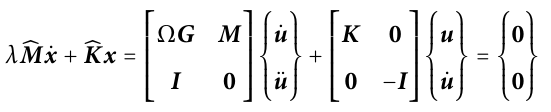

Mhat = zeros(2*numDOF,2*numDOF);
Khat = zeros(2*numDOF,2*numDOF);

Mhat(1:numDOF,1:numDOF) = Omega*G;
Mhat(1:numDOF,numDOF+1:end) = M;
Mhat(numDOF+1:end,1:numDOF) = eye(numDOF);
Khat(1:numDOF,1:numDOF) = K;
Khat(numDOF+1:end,numDOF+1:end) = -eye(numDOF);

[phi,eigVal] = eig(Khat,-Mhat);

poles = diag(eigVal);
indBC = find(double(abs(imag(poles))<0.2*2*pi));
poles(indBC,:) = [];
phi(:,indBC) = [];

poles = flip(real(poles) + 1i*imag(poles)/(2*pi));
phi = flip(phi,2);
fn  = imag(poles(2:2:end));
phi = phi(:,2:2:end);

[fn,ind] = sort(fn);
phi = phi(:,ind);
fn(1:8)

ans =    22.8767
   23.3477
   87.7270
   90.5610
  164.8926
  170.5196
  274.2117
  279.7614


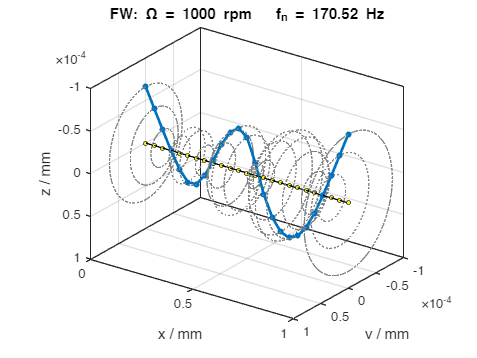

numMode = "6";
plotWhirl(FE,phi(:,str2num(numMode)),Omega,fn(str2num(numMode)))

#### Subfunctions

function MAC = compMAC(phi1,phi2)

m = size(phi1,2);
n = size(phi2,2);

for i=1:m
    for j=1:n
        MAC(i,j) = real(phi1(:,i)'*phi2(:,j))^2/((phi1(:,i)'*phi1(:,i))*(phi2(:,j)'*phi2(:,j)));
    end
end

end

function preProc(FE)

figure;

numN = length(FE.N);
line(FE.N,zeros(2,numN),zeros(2,numN),'Color',[ 0 0 0 ],'LineWidth',2)
line(FE.N,zeros(2,numN),zeros(2,numN),'Color',[ 0 0 0 ],'LineStyle','none','Marker','o','MarkerSize',5,'MarkerFaceColor',[1 1 0.0667],'LineWidth',1)
view(36,24)
set(gca, 'Zdir', 'reverse')
set(gca, 'Ydir', 'reverse')
set(gca,'YLim',[-1 1],'ZLim',[-1 1])
grid on
box on
xlabel 'x'
ylabel 'y'
zlabel 'z'

text(FE.N,zeros(1,numN),zeros(1,numN),num2cell(1:numN),'VerticalAlignment','bottom','FontSize',8)

L = abs(max(FE.N) - min(FE.N));
scal = 0.2*L;
set(gca,'DataAspectRatioMode','manual','DataAspectRatio',[scal 1 1])

alpha = linspace(0,2*pi,100);
diskY = 0.3*sin(alpha);
diskZ = 0.3*cos(alpha);

hold on
numRD = size(FE.RD,1);
for i=1:numRD
    patch('Faces',1:100,'Vertices',[FE.N(FE.RD(i,1))*ones(100,1) diskY' diskZ'],'FaceColor',[ 0  0.4471  0.7412 ],'FaceAlpha',0.3)
    hold on
end
hold off
line(FE.N(FE.RD(:,1)),zeros(1,numRD),zeros(1,numRD),'Marker','o','MarkerFaceColor',[0  0.4471  0.7412])

numBC = size(FE.BC,1);
line(FE.N(FE.BC(:,1)),zeros(1,numBC),zeros(1,numBC),'Marker','o','MarkerFaceColor',[0.8510  0.3255  0.0980],'MarkerEdgeColor',[0.8510  0.3255  0.0980],'MarkerSize',7)

end
